### Growth in 10% Compost Wastewater

This experiment measured the growth of R. Palustris in 10% compost wastewater in 8 test tubes labelled A through H. There is no difference between samples. Data collection began on 03/08. Optical density was measured approximately every 12 hours until growth plateaued on [].

clear
clf

data = readmatrix('rpalus_10percent_03112023.csv');
num_datapoints = (length(data));

% label data from csv
time = data(:, 1) / 60;     % hours
A = data(:, 2); % optical density
B = data(:, 3); % optical density
C = data(:, 4); % optical density
D = data(:, 5); % optical density
E = data(:, 6); % optical density
F = data(:, 7); % optical density
G = data(:, 8); % optical density
H = data(:, 9); % optical density

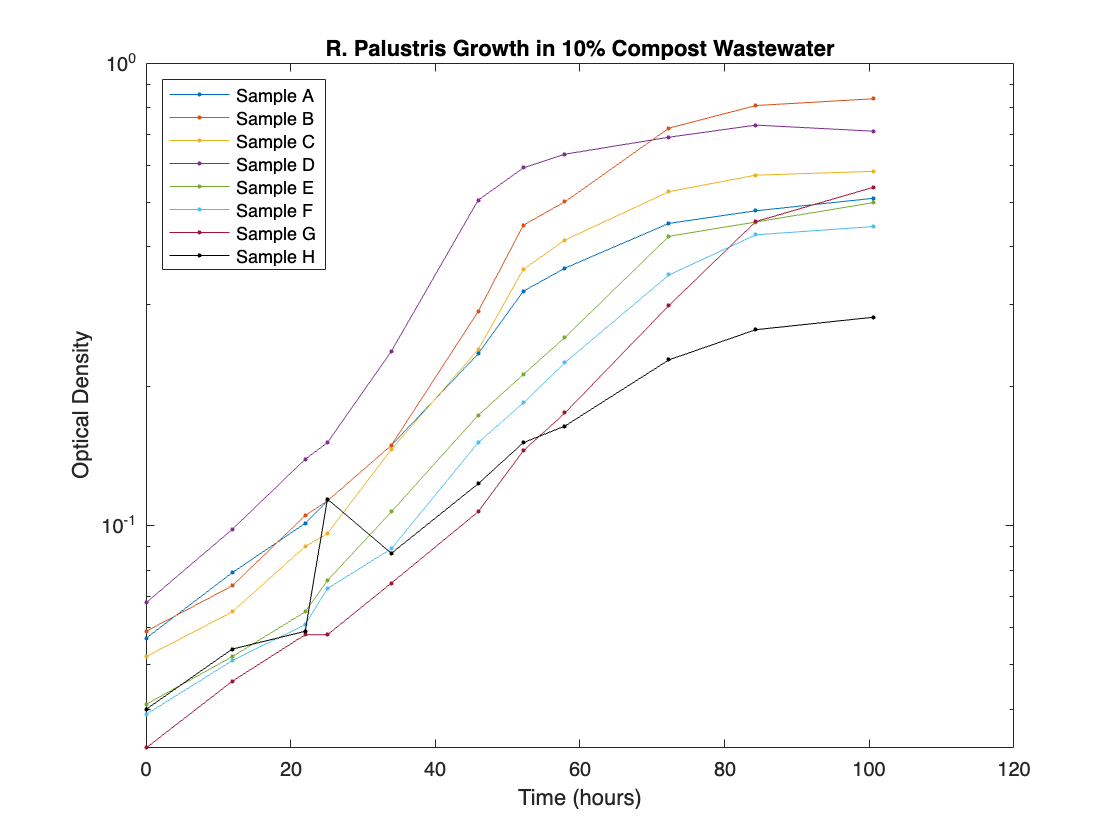

figure
semilogy(time, A, '.    -');
hold on
semilogy(time, B, '.-');
semilogy(time, C, '.-');
semilogy(time, D, '.-');
semilogy(time, E, '.-');
semilogy(time, F, '.-');
semilogy(time, G, '.-');
semilogy(time, H, 'k.-');

title("R. Palustris Growth in 10% Compost Wastewater")
xlabel("Time (hours)")
ylabel("Optical Density")
legend("Sample A","Sample B","Sample C","Sample D", ...
        "Sample E","Sample F","Sample G", "Sample H", ...
        "Location", "northwest")
hold off

## Fitting & Analysis

### Sample A

We isolated the exponential section of the sample A curve, which happens between the 1st and 6th data point.

isolate_A = 1:6;

We can now use the `fit_data` function to get an exponential fit.

[fitobjectA, gofA] = fit_data(A, isolate_A, time)

fitobjectA =      General model Exp1:
     fitobjectA(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =     0.05034  (0.04261, 0.05806)
       b =     0.03317  (0.02908, 0.03726)

gofA = struct with fields:
           sse: 1.3521e-04
       rsquare: 0.9933
           dfe: 4
    adjrsquare: 0.9916
          rmse: 0.0058


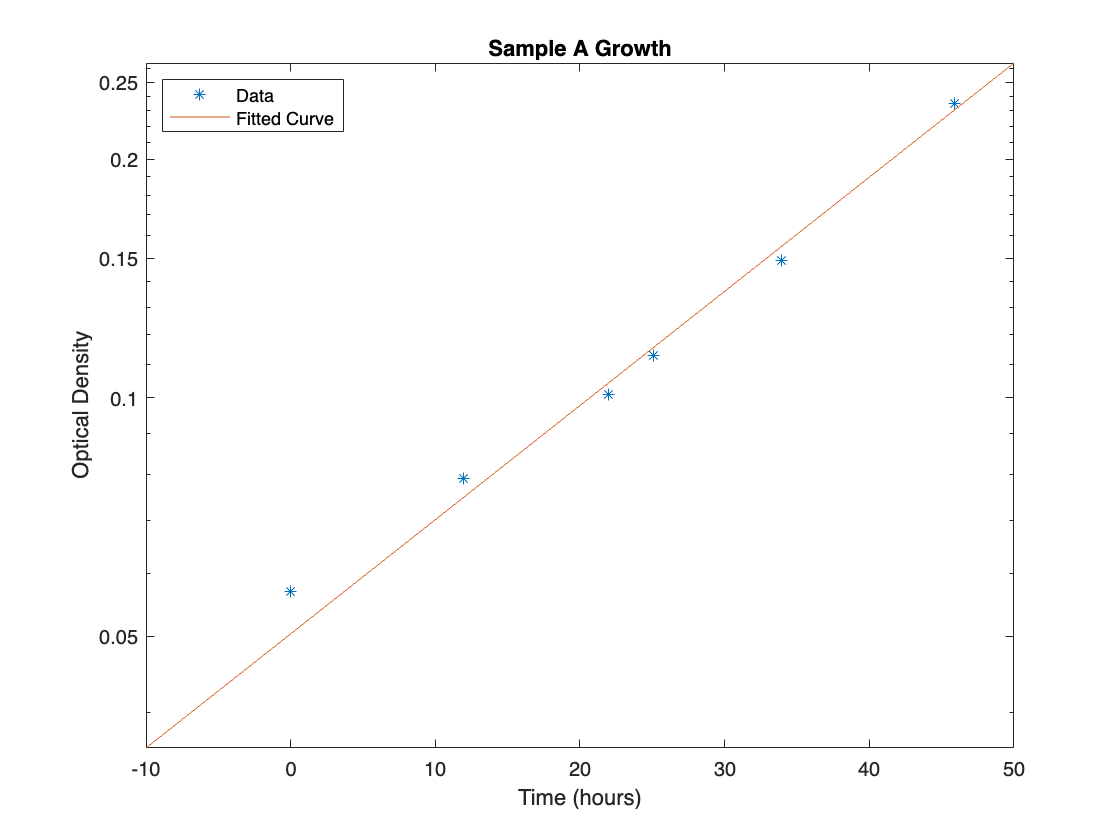

title("Sample A Growth")

The `fit` function outputs an exponential fit of:


$$f\left(x\right)=0\ldotp 05034*e^{0\ldotp 03317x}$$


with an r squared value of 0.9933. 

### Sample B

We isolated the exponential section of the sample B curve, which happens between the 1st and 8th data point.

isolate_b = 1:8;

We can now use the `fit_data` function to get an exponential fit.

[fitobjectB, gofB] = fit_data(B, isolate_b, time)

fitobjectB =      General model Exp1:
     fitobjectB(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =     0.03815  (0.02134, 0.05496)
       b =     0.04512  (0.03667, 0.05357)

gofB = struct with fields:
           sse: 0.0038
       rsquare: 0.9820
           dfe: 6
    adjrsquare: 0.9790
          rmse: 0.0252


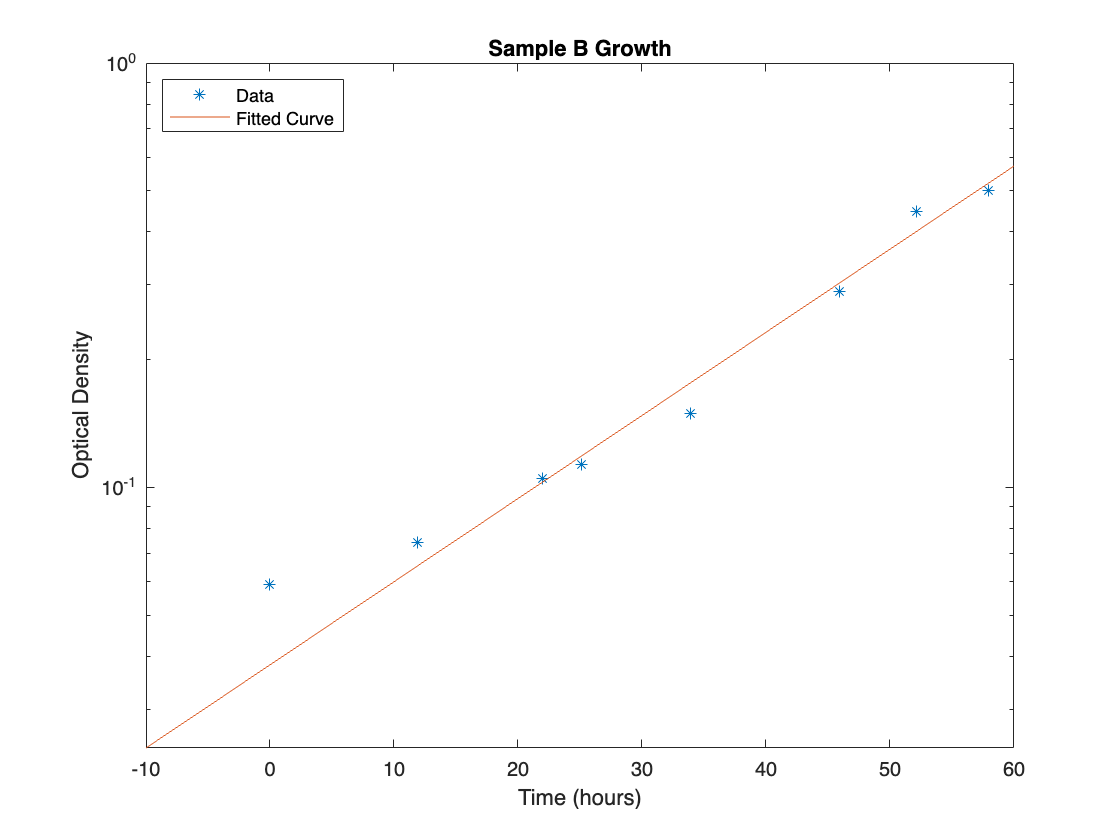

title("Sample B Growth")

The `fit` function outputs an exponential fit of:


$$f\left(x\right)=0\ldotp 03815*e^{0\ldotp 04512x}$$


with an r squared value of 0.9820. 

### Sample C

We isolated the exponential section of the sample C curve, which happens between the 1st and 7th data point.

isolate_c = 1:7;

We can now use the `fit_data` function to get an exponential fit.

[fitobjectC, gofC] = fit_data(C, isolate_c, time)

fitobjectC =      General model Exp1:
     fitobjectC(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =     0.03265  (0.02052, 0.04477)
       b =     0.04512  (0.03715, 0.05309)

gofC = struct with fields:
           sse: 0.0011
       rsquare: 0.9855
           dfe: 5
    adjrsquare: 0.9826
          rmse: 0.0147


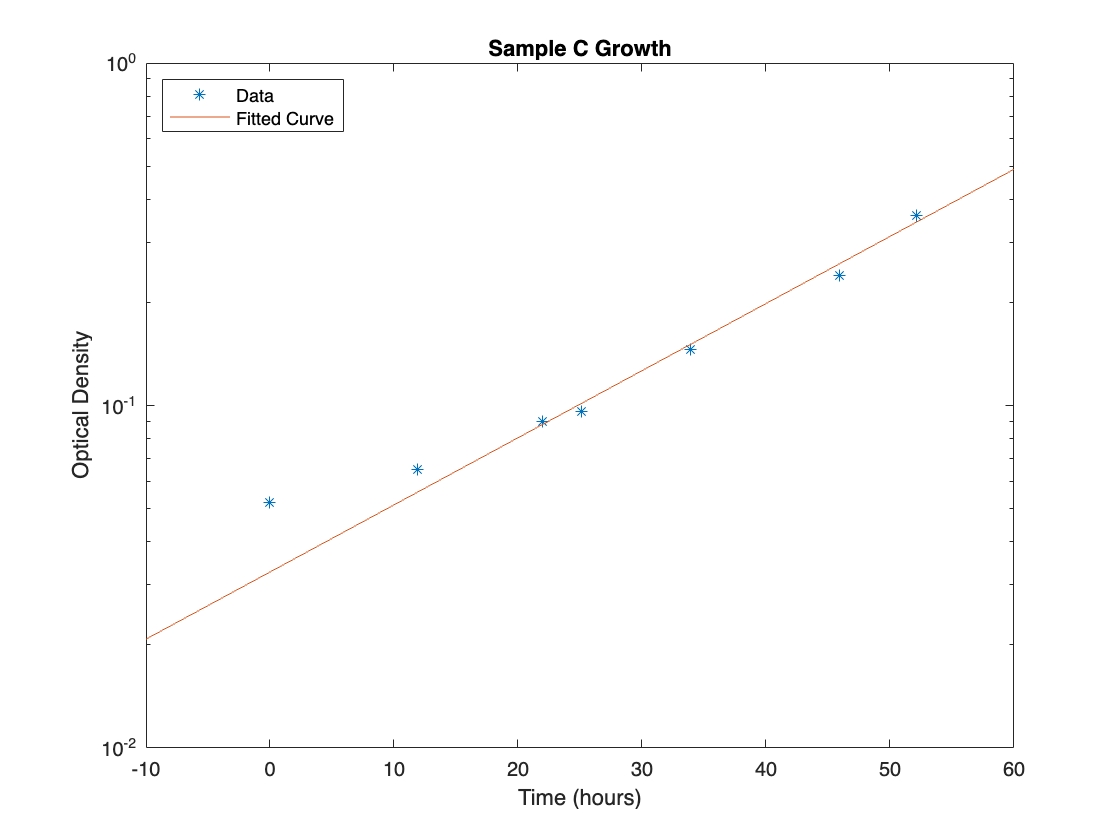

title("Sample C Growth")

The `fit` function outputs an exponential fit of:


$$f\left(x\right)=0\ldotp 03265*e^{0\ldotp 04512x}$$


with an r squared value of 0.9855. 

### Sample D

We isolated the exponential section of the sample D curve, which happens between the 1st and 6th data point.

isolate_d = 1:6;

We can now use the `fit_data` function to get an exponential fit.

[fitobjectD, gofD] = fit_data(D, isolate_d, time)

fitobjectD =      General model Exp1:
     fitobjectD(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =     0.04209  (0.02421, 0.05997)
       b =      0.0537  (0.04339, 0.06401)

gofD = struct with fields:
           sse: 0.0017
       rsquare: 0.9867
           dfe: 4
    adjrsquare: 0.9834
          rmse: 0.0206


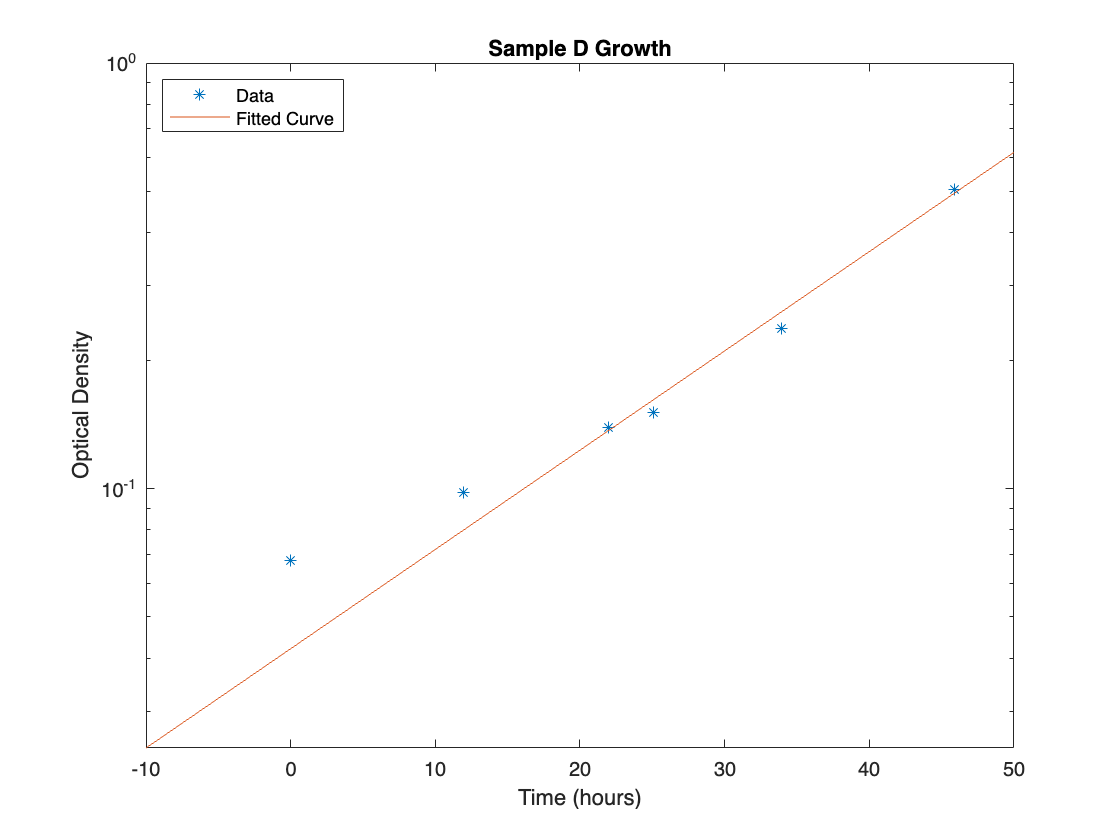

title("Sample D Growth")

The `fit` function outputs an exponential fit of:


$$f\left(x\right)=0\ldotp 04209*e^{0\ldotp 0537x}$$


with an r squared value of 0.9867. 

### Sample E

We isolated the exponential section of the sample E curve, which happens between the 1st and 9th data point.

isolate_e = 1:9;

We can now use the `fit` function to get an exponential fit.

[fitobjectE, gofE] = fit_data(E, isolate_e, time)

fitobjectE =      General model Exp1:
     fitobjectE(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =     0.03345  (0.03037, 0.03652)
       b =      0.0351  (0.03364, 0.03657)

gofE = struct with fields:
           sse: 1.8518e-04
       rsquare: 0.9985
           dfe: 7
    adjrsquare: 0.9983
          rmse: 0.0051


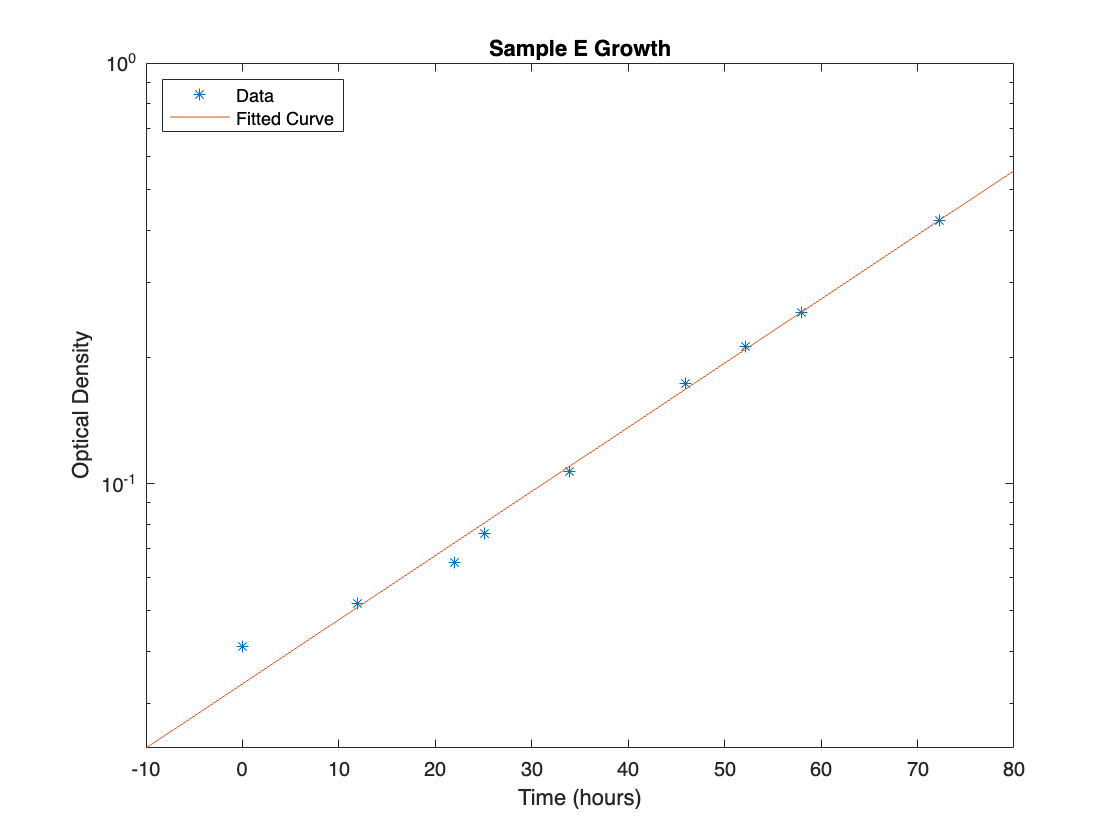

title("Sample E Growth")

The `fit` function outputs an exponential fit of:


$$f\left(x\right)=0\ldotp 03345*e^{0\ldotp 0351x}$$


with an r squared value of 0.9985. 

### Sample F

We isolated the exponential section of the sample F curve, which happens between the 1st and 6th data point.

isolate_f = 1:9;

We can now use the `fit_data` function to get an exponential fit.

[fitobjectF, gofF] = fit_data(F, isolate_f, time)

fitobjectF =      General model Exp1:
     fitobjectF(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =     0.03262  (0.02863, 0.03661)
       b =     0.03287  (0.0309, 0.03484)

gofF = struct with fields:
           sse: 2.6554e-04
       rsquare: 0.9968
           dfe: 7
    adjrsquare: 0.9964
          rmse: 0.0062


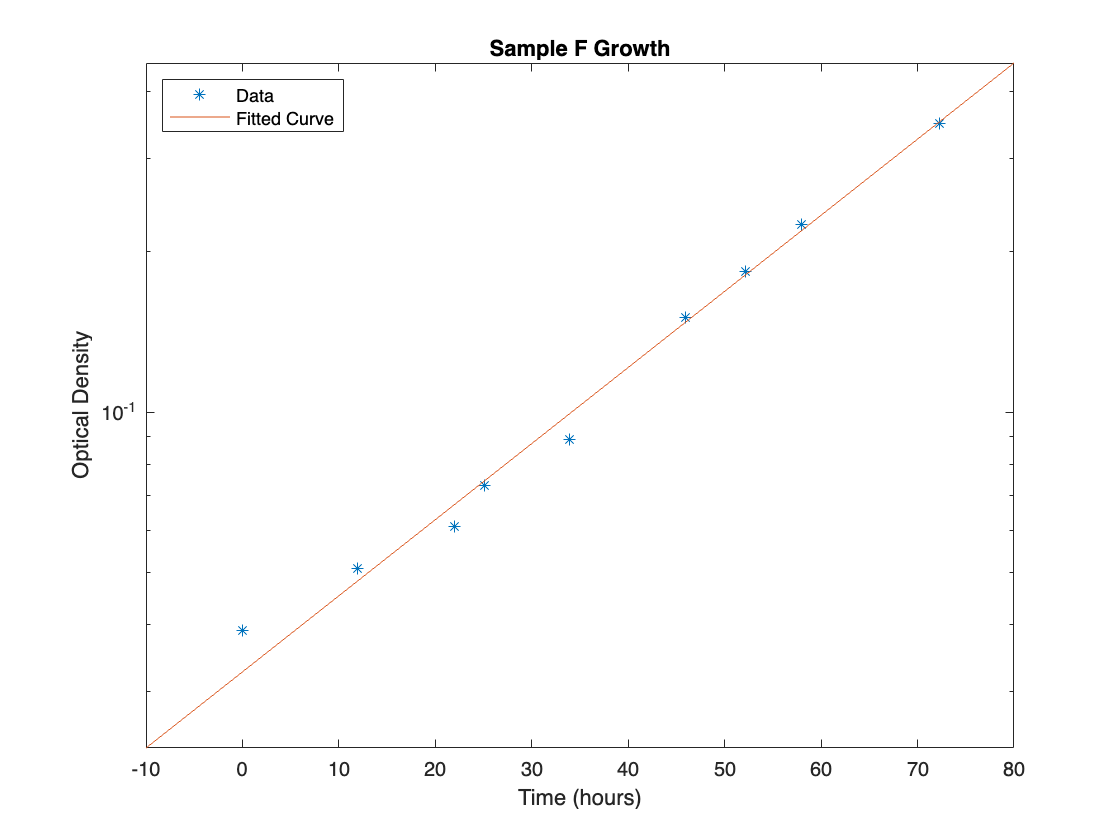

title("Sample F Growth")

The `fit` function outputs an exponential fit of:


$$f\left(x\right)=0\ldotp 03263*e^{0\ldotp 03287x}$$


with an r squared value of 0.9968. 

### Sample G

We isolated the exponential section of the sample G curve, which happens between the 1st and 10th data point.

isolate_g = 1:10;

We can now use the `fit_data` function to get an exponential fit.

[fitobjectG, gofG] = fit_data(G, isolate_g, time)

fitobjectG =      General model Exp1:
     fitobjectG(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =     0.02341  (0.02028, 0.02655)
       b =     0.03513  (0.03336, 0.03691)

gofG = struct with fields:
           sse: 3.9554e-04
       rsquare: 0.9976
           dfe: 8
    adjrsquare: 0.9973
          rmse: 0.0070


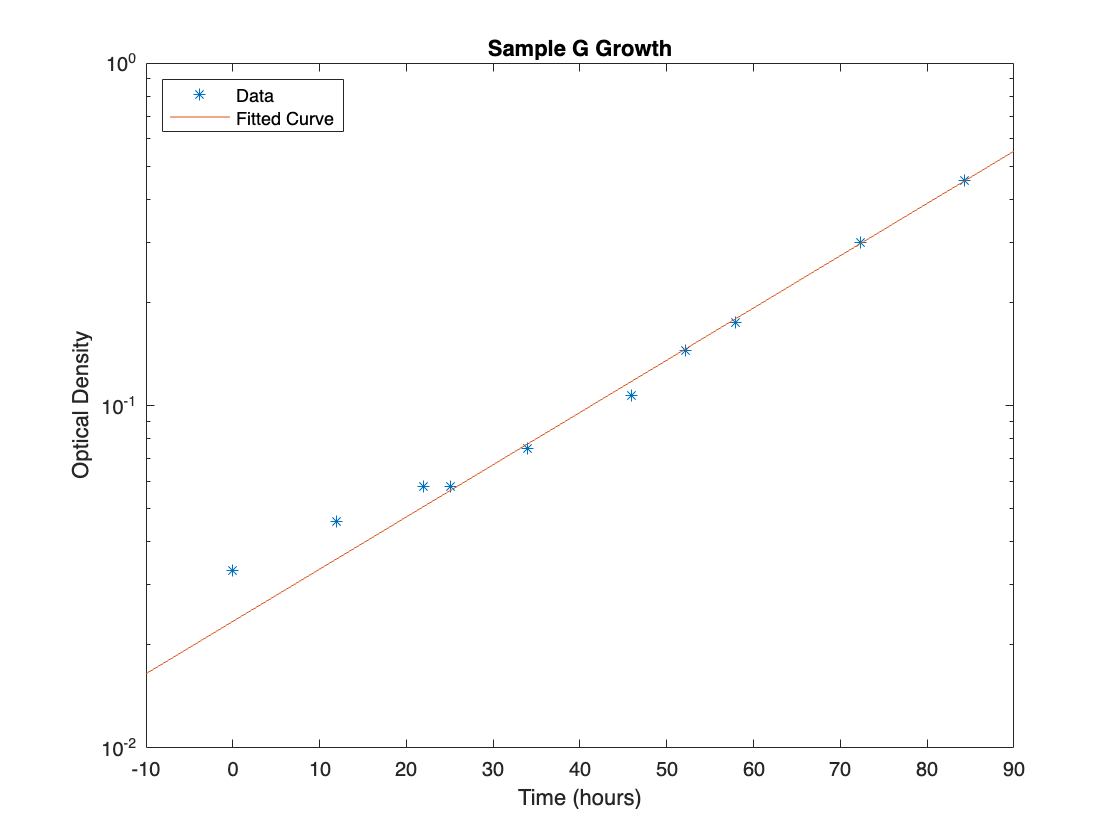

title("Sample G Growth")

The `fit` function outputs an exponential fit of:


$$f\left(x\right)=0\ldotp 02341*e^{0\ldotp 03513x}$$


with an r squared value of 0.9973. 

### Sample H

We isolated the exponential section of the sample H curve, which happens between the 1st and 9th data point. Note that we exclude the 4th data point because it is an outlier.

isolate_h = [1:3,5:9];

We can now use the `fit_data` function to get an exponential fit.

[fitobjectH, gofH] = fit_data(H, isolate_h, time)

fitobjectH =      General model Exp1:
     fitobjectH(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =     0.03933  (0.03384, 0.04481)
       b =     0.02455  (0.0222, 0.02689)

gofH = struct with fields:
           sse: 1.9525e-04
       rsquare: 0.9934
           dfe: 6
    adjrsquare: 0.9923
          rmse: 0.0057


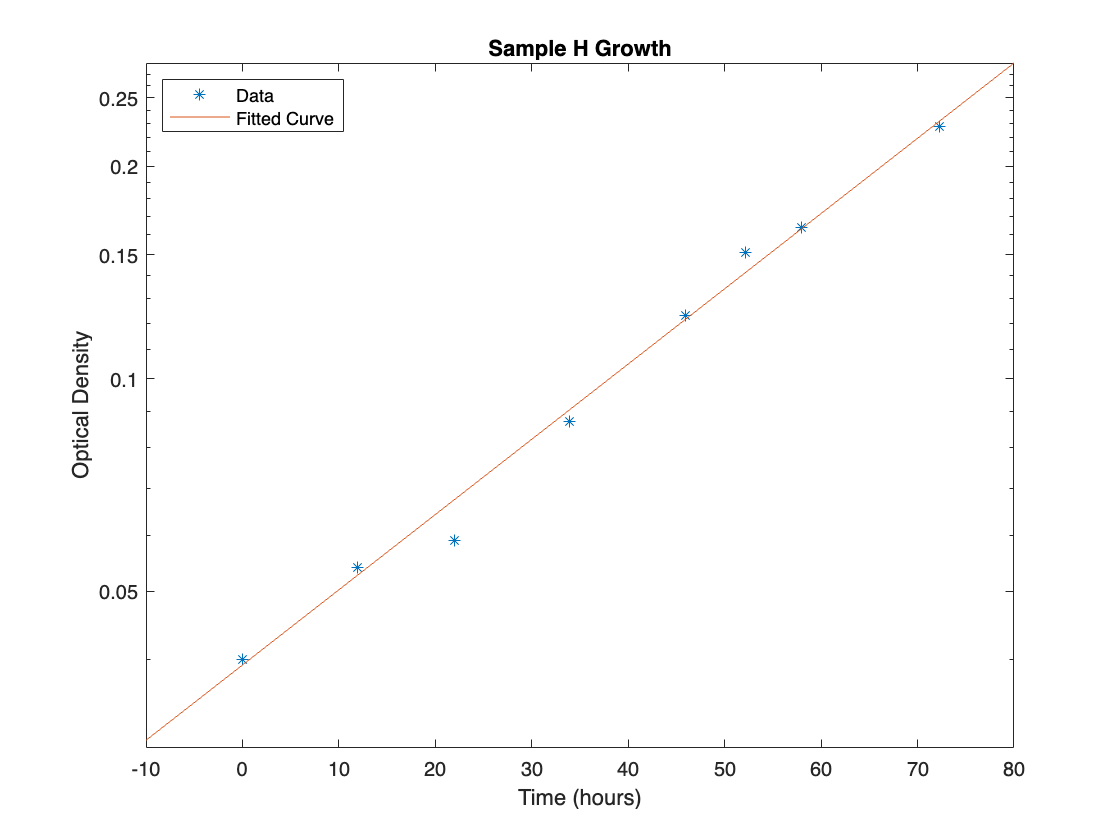

title("Sample H Growth")

The `fit` function outputs an exponential fit of:


$$f\left(x\right)=0\ldotp 03933*e^{0\ldotp 02455x}$$


with an r squared value of 0.9934. 

## Results

For the general fit equation $f\left(x\right)=a*e^{\mathrm{bx}}$, the following values for b were extracted for samples A-H (respectively): 0.03317, 0.04512, 0.04512, 0.05370, 0.03510, 0.03287, 0.03513, 0.02455.